# Cerinte de performanta

% Ts = 0.2
% overshoot - 0-10%
% eroare stationara aproape 0
% saturare pwm (0-255)
% PM robust


## Identificare Controller PI

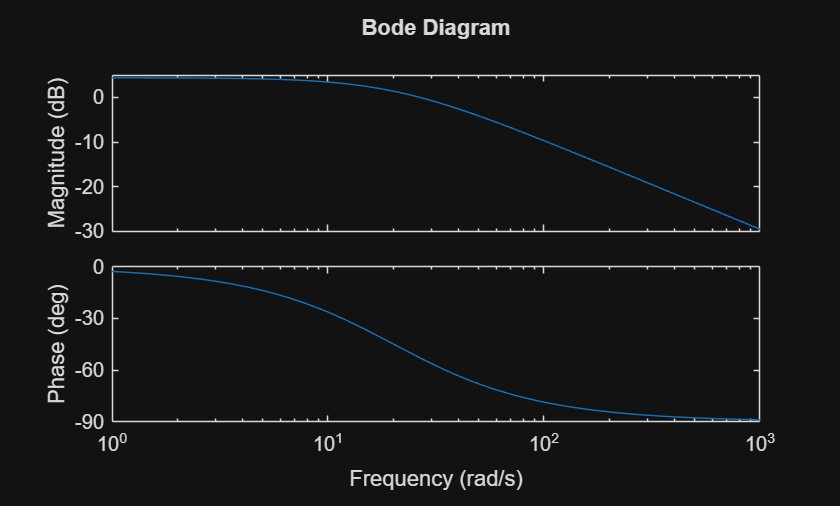

s = tf('s');
P = 0.8311/(0.04964*s + 1);
C = 2;
L = P*C;

figure
bode(L)

%iau frecventa de taiere si asez zeroul PI
wc = 20;
z = wc/2;
C0 = (s + z)/s;
K = 1 / abs(evalfr(P*C0, 1j*wc)) % gasesc gainul K

K = 1.5165

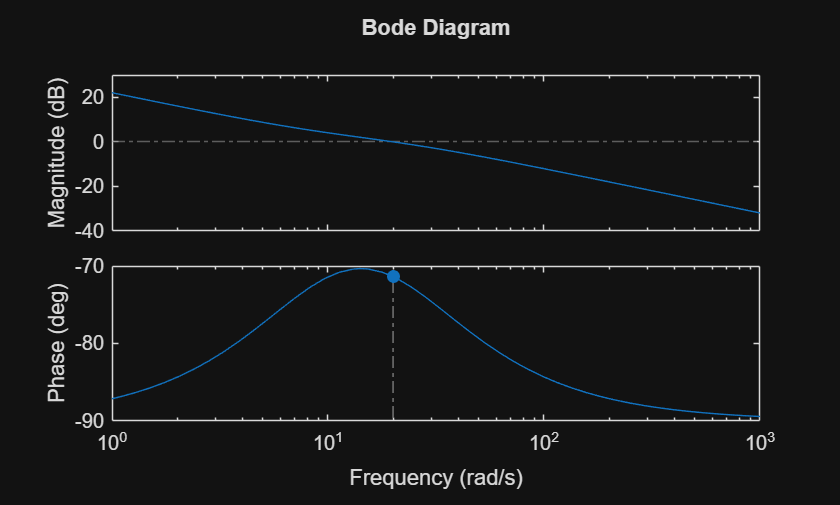

C = K*C0;
L = P*C;

figure
margin(L)

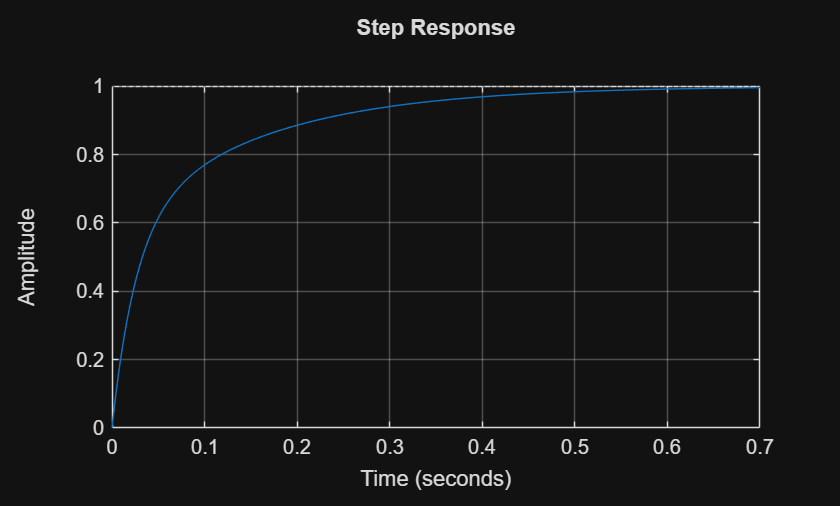

T = feedback(P*C,1);
figure
step(T)
grid on

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.2163
    TransientTime: 0.4678
     SettlingTime: 0.4678
      SettlingMin: 0.9008
      SettlingMax: 0.9977
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9977
         PeakTime: 0.8000


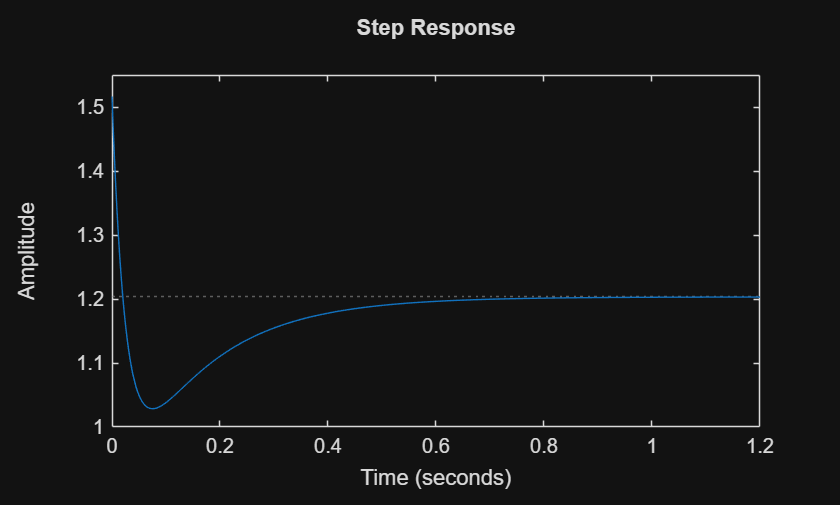

U = feedback(C,P);
figure
step(U)

Ts = 0.05;  % sample time = 50ms
C_disc = c2d(C, Ts, 'tustin') 


C_disc =
 
  1.896 z - 1.137
  ---------------
       z - 1
 
Sample time: 0.05 seconds
Discrete-time transfer function.
